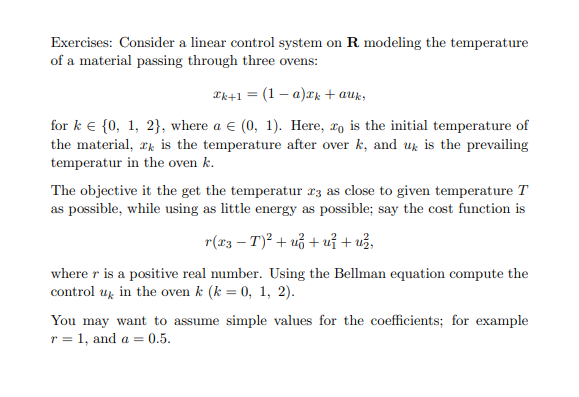

r = 1;
a = 0.5;
syms x0 x1 x2 x3 u0 u1 u2 u3 T;
% x=(1-a)*x+a*u

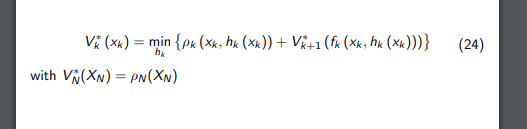

We start from Bellman equations (value equations), for which we begin from "behind". We know the cost function related to x3, V3, which is given, we now want to propegate that cost down by going "backwards":

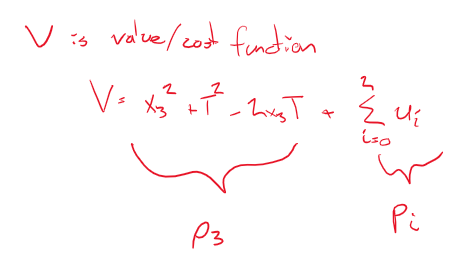

V3 = r*(x3-T)^2                                                             %  =x3^2+T^2-2x3T

$$V3 = {\left(T-x_{3}\right)}^{2}$$

Note that the cost at x3, does not depend on u, as the sum from 3 to 2, does not make sence.

We now insert the value of x3 fom the equation for x_(k+1):

V3 = r*(((1-a)*x2+a*u2)-T)^2

$$V3 = {\left(\frac{u_{2}}{2}-T+\frac{x_{2}}{2}\right)}^{2}$$

We now write V2:

V2 = @(x2,u2) u2^2 + r*(((1-a)*x2+a*u2)-T)^2

V2 = function_handle with value:
    @(x2,u2)u2^2+r*(((1-a)*x2+a*u2)-T)^2


u2 = solve(diff(V2,u2)==0,u2)

$$u2 = \frac{2\,T}{5}-\frac{x_{2}}{5}$$

We insert u2, and value for x2 from equation x_(k+1), and simplify:

V2 = @(x1,u1) ((2*T)/5 - ((1-a)*x1+a*u1)/5)^2 + r*(((1-a)*((1-a)*x1+a*u1)+a*((2*T)/5 - ((1-a)*x1+a*u1)/5))-T)^2

V2 = function_handle with value:
    @(x1,u1)((2*T)/5-((1-a)*x1+a*u1)/5)^2+r*(((1-a)*((1-a)*x1+a*u1)+a*((2*T)/5-((1-a)*x1+a*u1)/5))-T)^2


S = simplify(((2*T)/5 - ((1-a)*x1+a*u1)/5)^2 + r*(((1-a)*((1-a)*x1+a*u1)+a*((2*T)/5 - ((1-a)*x1+a*u1)/5))-T)^2)

$$S = \frac{{\left(u_{1}-4\,T+x_{1}\right)}^{2}}{20}$$

We have found an expresion for the optimal value of u2, we now propegate one down, finding V1:

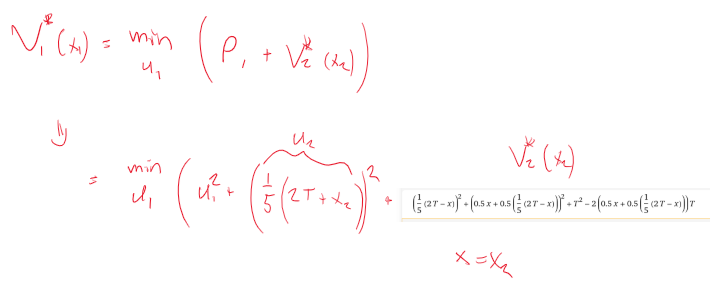

V1 = @(x1,u1) u1^2+((2/5)*T-((1-a)*x1+a*u1)/5)^2 + (u1 - 4*T + x1)^2/20

V1 = function_handle with value:
    @(x1,u1)u1^2+((2/5)*T-((1-a)*x1+a*u1)/5)^2+(u1-4*T+x1)^2/20


u1 = solve(diff(V1,u1)==0,u1)

$$u1 = \frac{12\,T}{53}-\frac{3\,x_{1}}{53}$$

We simplify like before:

V1 = @(x0,u0) ((12*T)/53 - (3*((1-a)*x0+a*u0))/53)^2+((2/5)*T-((1-a)*((1-a)*x0+a*u0)+a*((12*T)/53 - (3*((1-a)*x0+a*u0))/53))/5)^2 + (((12*T)/53 - (3*((1-a)*x0+a*u0))/53) - 4*T + ((1-a)*x0+a*u0))^2/20

V1 = function_handle with value:
    @(x0,u0)((12*T)/53-(3*((1-a)*x0+a*u0))/53)^2+((2/5)*T-((1-a)*((1-a)*x0+a*u0)+a*((12*T)/53-(3*((1-a)*x0+a*u0))/53))/5)^2+(((12*T)/53-(3*((1-a)*x0+a*u0))/53)-4*T+((1-a)*x0+a*u0))^2/20


S = simplify(((12*T)/53 - (3*((1-a)*x0+a*u0))/53)^2+((2/5)*T-((1-a)*((1-a)*x0+a*u0)+a*((12*T)/53 - (3*((1-a)*x0+a*u0))/53))/5)^2 + (((12*T)/53 - (3*((1-a)*x0+a*u0))/53) - 4*T + ((1-a)*x0+a*u0))^2/20)

$$S = \frac{3\,{\left(u_{0}-8\,T+x_{0}\right)}^{2}}{212}$$

We now find V0:

Here we insert the function for x, until we only have x0, and then insert our found optimal values for u1 and u2 everywhere they appear, this leaves us with a function of x0 and u0:

V0 = @(x0,u0) u0^2+((12*T)/53 - (3*((1-a)*x0+a*u0))/53)^2+((2*T)/5 - ((1-a)*((1-a)*x0+a*u0)+a*((12*T)/53 - (3*((1-a)*x0+a*u0))/53))/5)^2 + (3*(u0 - 8*T + x0)^2)/212

V0 = function_handle with value:
    @(x0,u0)u0^2+((12*T)/53-(3*((1-a)*x0+a*u0))/53)^2+((2*T)/5-((1-a)*((1-a)*x0+a*u0)+a*((12*T)/53-(3*((1-a)*x0+a*u0))/53))/5)^2+(3*(u0-8*T+x0)^2)/212


u0 = solve(diff(V0,u0)==0,u0)

$$u0 = \frac{1544\,T}{11429}-\frac{193\,x_{0}}{11429}$$

We now have all the u functions:

u0

$$u0 = \frac{1544\,T}{11429}-\frac{193\,x_{0}}{11429}$$

T = 100; x0 = 30;
u0 = (1544/11429) * T - (193/11429)*x0

u0 = 13.0029


u1

$$u1 = \frac{12\,T}{53}-\frac{3\,x_{1}}{53}$$

x1 = (1-a)*x0+a*u0

x1 = 21.5014

u1 = (12/53)*T - (3/53)*x1

u1 = 21.4244


u2

$$u2 = \frac{2\,T}{5}-\frac{x_{2}}{5}$$

x2 = (1-a)*x1+a*u1

x2 = 21.4629

u2 = (2/5)*T-x2/5

u2 = 35.7074


x3 = (1-a)*x2+a*u2

x3 = 28.5852


% A = [1 0 0 0 0 0 0;
%     0 1 0 0 0 0 0;
%     -(193)/11429 (1544)/11429 0 0 0 0 0;
%     0 12/53 0 0 0 -3/53 0;
%     0 2/5 0 0 0 0 -1/5;
%     (1-a) 0 a 0 0 0 0;
%     0 0 0 a 0 (1-a) 0;]
% 
% B = [1 10 0 0 0 0 0]'
% 
% result = pinv(A)*B